# Evaluate the influence of arrival-time uncertainties on event localization

## Introduction

This script reproduces Figures 7 published in the paper:

Abakumov, I., Roeser, A., and S. A. Shapiro (2020) The arrival time picking uncertainty: theoretical estimationsand their application to microseismic data, Geophysics

**Authors**: I. Abakumov, A. Roeser, S.A. Shapiro

**Publication date**: 20th of February 2020

**E-mail**: abakumov_ivan@mail.ru

## Add MLIB library

In this project we use several functions from MLIB library. 

You can download the whole library at github:

https://github.com/Abakumov/MLIB

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Load event file

Events = MLD('/local_ssd/ivan/ESG/mat/Events_ivan_STALTA.mat');

## Make G-file

G=GridClass;

% [m]        [m]          [m]          [s]
G.x0=-200;  G.y0=-650;  G.z0=1400;     G.t0 = 0.00;          % initial point
G.nx=201;   G.ny=251;   G.nz=126;      G.nt = 6000;          % grid size
G.dx=4;     G.dy=4;     G.dz=4;        G.dt = 0.00025;       % grid step (meter)

G.gridInfo;

Information about grid:
x0=-200, dx=4, Nx=201.
y0=-650, dy=4, Ny=251.
z0=1400, dz=4, Nz=126.
t0=0, dt=0.00025, Nt=6000.


G.setGrid;
Gold = oldGrid(G);

## Load event file

Events = MLD('/local_ssd/ivan/ESG/mat/Events_sponsor.mat');

PTTI = MLD('/local_ssd/ivan/ESG/tti_tables/PTTIFSM.mat');

STTI = MLD('/local_ssd/ivan/ESG/tti_tables/STTIFSM.mat');

Gtti = MLD('/local_ssd/ivan/ESG/tti_tables/G_file.mat');

## Acquisition

acq.sx = Events(1).SensorEasting;
acq.sy = Events(1).SensorNorthing;
acq.sz = Events(1).SensorDepth;

## Create traveltime

nsta = length(acq.sx);
Ptti = zeros(G.nx,G.ny,G.nz,nsta); 
Stti = zeros(G.nx,G.ny,G.nz,nsta); 

for s=1:nsta
    for i=1:G.nx
        for j=1:G.ny
            off = sqrt((acq.sx(s)-G.xx(i)).^2 + (acq.sy(s)-G.yy(j)).^2);
            goff = x2grid(off,Gtti.x0,Gtti.dx,Gtti.nx);
            Ptti(i,j,:,s) = squeeze(PTTI(goff,1:4:501,s));
            Stti(i,j,:,s) = squeeze(STTI(goff,1:4:501,s));
        end
    end
end

## Start localization of events

event =  801;

## Upload traveltimes of P- and S-waves

% P-wave arrival time (in seconds)
Tp(1:nsta,1) = 0; 
for i=1:length(Events(event).PTime)
    Tp(i) = Events(event).PTime(i);
end

% S-wave arrival time (in seconds)
Ts(1:nsta,1) = 0; 
for i=1:length(Events(event).STime)
    Ts(i) = Events(event).STime(i);
end

## Create SNR

tmin = 0.4;
tmax = 0.7;

ind1 = ((G.tt > tmin) == 1);
ind2 = ((G.tt < tmax) == 1);
ind = (ind1 + ind2 == 2);

Tx = zeros(G.nt,31);
Ty = zeros(G.nt,31);
Tz = zeros(G.nt,31);

Tx(ind,:) = Events(event).tracesx(ind,:); 
Ty(ind,:) = Events(event).tracesy(ind,:); 
Tz(ind,:) = Events(event).tracesz(ind,:); 

get_beta = @(signal,dt)(   sqrt(sum((diff(signal,1)/dt).^2)/sum(signal.^2))   );
get_CRB = @(SNR,beta)(   1./beta.^2./SNR   );

[~, indm] = max(abs(Tx));
Tm = G.tt(indm);
fd = 400;   % dominant frequency == beta/2/pi
Td = 1/400;  % dominant period


W = zeros(1,31); 
N0 = zeros(1,31);
Beta = zeros(1,31);

for i=2:31 
    tnmin = x2grid(Tp(i)-0.02,  G.t0, G.dt, G.nt); 
    tnmax = x2grid(Tp(i)-0.005, G.t0, G.dt, G.nt); 

    tsmin = x2grid(Tm(i)-Td,    G.t0, G.dt, G.nt); 
    tsmax = x2grid(Tm(i)+Td,    G.t0, G.dt, G.nt);
        
    indn = tnmin:tnmax; 
    inds = tsmin:tsmax; 
    
    signal = Tx(inds,i);
    noise  = Tx(indn,i);
    
    N0(i) = var(noise)*G.dt;
    W(i)  = sum(signal.^2)*G.dt;
    Beta(i) = get_beta(signal,G.dt);
end

W = W-N0*length(inds);

SNR = W./N0;
SNRdb = 10*log10(SNR);
beta = mean(Beta(2:31));
CRB = get_CRB(SNR,beta);
err = sqrt(CRB)*1000*1.96*3; % in ms, + 95% confidence interval

## Compute PDF

weight = zeros(size(err));
weight(err <= 0.1) = 2; 
weight((err > 0.1) + (err <= 0.2) == 2) = 1; 
weight((err > 0.2) + (err <= 0.3) == 2) = .5; 
weight(err > 0.3) = .25; 
weight(1) = 1; 


dTp(1:nsta,1) = 0.003;            % Accuracy of P-wave arrival time (in seconds)
dTs(1:nsta,1) = 0.003;            % Accuracy of S-wave arrival time (in seconds)

pdfT = zeros(G.nx,G.ny,G.nz); 
for s=1:nsta
    if Tp(s)>0
        pdfT = pdfT + Tp(s) - Ptti(:,:,:,s);
    end
    if Ts(s)>0
        pdfT = pdfT + Ts(s) - Stti(:,:,:,s);
    end
end
pdfT = pdfT/(sum(Tp>0)+sum(Ts>0)); 


pdf = zeros(G.nx, G.ny, G.nz); 
for s=1:nsta
    if Tp(s)>0
        pdf = pdf - ((Tp(s)-Ptti(:,:,:,s)-pdfT)/dTp(s)).^2/2;
    end
    if Ts(s)>0
        pdf = pdf - ((Ts(s)-Stti(:,:,:,s)-pdfT)/dTs(s)).^2/2;
    end
end
pdf = exp(pdf)/(sum(exp(pdf(:))));
pdf1 = pdf;

%Find optimal location 
[pdfi1, pdfj1, pdfk1, pdfx1, pdfy1, pdfz1] = get_max_of_pdf(pdf1, G); 
T0pdf = pdfT(pdfi1,pdfj1,pdfk1);

PDF1.sx = pdfx1; 
PDF1.sy = pdfy1; 
PDF1.sz = pdfz1;
PDF1.t0 = T0pdf;
    

% now use weight
dTp = dTp./weight';
dTs = dTs./weight';

pdfT = zeros(G.nx,G.ny,G.nz); 
for s=1:nsta
    if Tp(s)>0
        pdfT = pdfT + Tp(s) - Ptti(:,:,:,s);
    end
    if Ts(s)>0
        pdfT = pdfT + Ts(s) - Stti(:,:,:,s);
    end
end
pdfT = pdfT/(sum(Tp>0)+sum(Ts>0)); 


pdf = zeros(G.nx, G.ny, G.nz); 
for s=1:nsta
    if Tp(s)>0
        pdf = pdf - ((Tp(s)-Ptti(:,:,:,s)-pdfT)/dTp(s)).^2/2;
    end
    if Ts(s)>0
        pdf = pdf - ((Ts(s)-Stti(:,:,:,s)-pdfT)/dTs(s)).^2/2;
    end
end
pdf = exp(pdf)/(sum(exp(pdf(:))));
pdf2 = pdf; 

% Find optimal location 
[pdfi2, pdfj2, pdfk2, pdfx2, pdfy2, pdfz2] = get_max_of_pdf(pdf2, G); 
T0pdf = pdfT(pdfi2,pdfj2,pdfk2);

PDF2.sx = pdfx2; 
PDF2.sy = pdfy2; 
PDF2.sz = pdfz2;
PDF2.t0 = T0pdf;

## Plot results

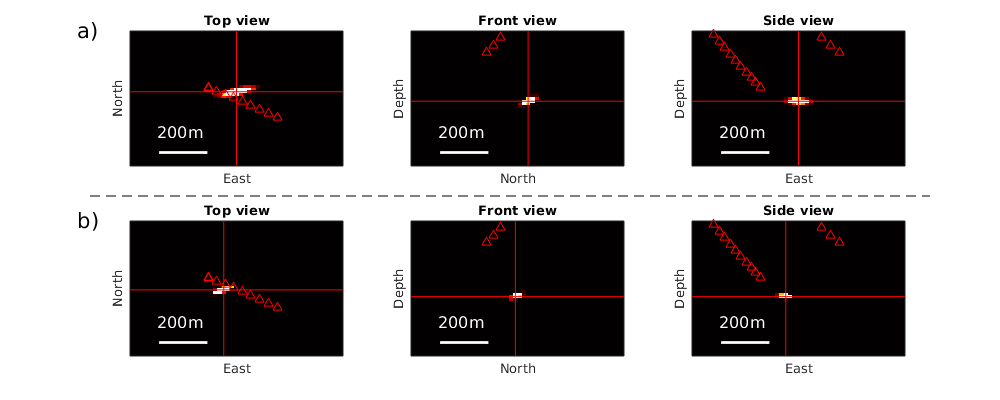

fig3 = figure(37355);
set(fig3, 'Position', [1 1 1000 400])
%fig3.Color = [240/255 240/255 240/255];
%fig3.InvertHardcopy = 'off'; 
% Create line
annotation(fig3,'line',[0.09 0.93],[0.51 0.51],'LineStyle','--');

subplot(2,3,1);
imagesc(G.xx,G.yy,squeeze((pdf1(:,:,pdfk1)))');
axis xy;
xlabel('East');
ylabel('North');
hold on
plot([G.xx(1),G.xx(end)],[G.yy(pdfj1),G.yy(pdfj1)],'r')
plot([G.xx(pdfi1),G.xx(pdfi1)],[G.yy(1),G.yy(end)],'r')
plot(acq.sx,acq.sy,'r^');
caxis([0 1e-2])
quiver(150, -80, 25, 0, 'white', 'Linewidth', 2),
quiver(150, -80, -25, 0, 'white', 'Linewidth', 2),
text(125,-50,'200m','FontSize',12, 'Color', 'w')
text(50,100,'a)','FontSize',16);
axis([100 300 -100 100])
xticks([]); 
yticks([]);
title('Top view')

subplot(2,3,2);
imagesc(G.yy,G.zz,squeeze((pdf1(pdfi1,:,:)))');
axis xy;
xlabel('North');
ylabel('Depth');
hold on
plot([G.yy(pdfj1),G.yy(pdfj1)],[G.zz(1),G.zz(end)],'r')
plot([G.yy(1),G.yy(end)],[G.zz(pdfk1),G.zz(pdfk1)],'r')
plot(acq.sy,acq.sz,'r^');
set(gca,'Ydir','reverse'); 
caxis([0 1e-2])
quiver(-50, 1780, 25, 0, 'white', 'Linewidth', 2),
quiver(-50, 1780, -25, 0, 'white', 'Linewidth', 2),
text(-75,1750,'200m','FontSize',12, 'Color', 'w')
axis([-100 100 1600 1800])
xticks([]); 
yticks([]);
title('Front view')

subplot(2,3,3);
imagesc(G.xx,G.zz,squeeze(pdf1(:,pdfj1,:))');
axis xy;
xlabel('East');
ylabel('Depth');
hold on
plot([G.xx(1),G.xx(end)],[G.zz(pdfk1),G.zz(pdfk1)],'r')
plot([G.xx(pdfi1),G.xx(pdfi1)],[G.zz(1),G.zz(end)],'r')
plot(acq.sx,acq.sz,'r^');
set(gca,'Ydir','reverse'); 
caxis([0 1e-2])
title('Side view')
quiver(150, 1780, 25, 0, 'white', 'Linewidth', 2),
quiver(150, 1780, -25, 0, 'white', 'Linewidth', 2),
text(125,1750,'200m','FontSize',12, 'Color', 'w')
axis([100 300 1600 1800])
xticks([]); 
yticks([]);

subplot(2,3,4);
imagesc(G.xx,G.yy,squeeze((pdf2(:,:,pdfk2)))');
axis xy;
xlabel('East');
ylabel('North');
hold on
plot([G.xx(1),G.xx(end)],[G.yy(pdfj2),G.yy(pdfj2)],'r')
plot([G.xx(pdfi2),G.xx(pdfi2)],[G.yy(1),G.yy(end)],'r')
plot(acq.sx,acq.sy,'r^');
caxis([0 1e-2])
quiver(150, -80, 25, 0, 'white', 'Linewidth', 2),
quiver(150, -80, -25, 0, 'white', 'Linewidth', 2),
text(125,-50,'200m','FontSize',12, 'Color', 'w')
text(50,100,'b)','FontSize',16);
axis([100 300 -100 100])
xticks([]); 
yticks([]);
title('Top view')

subplot(2,3,5);
imagesc(G.yy,G.zz,squeeze((pdf2(pdfi2,:,:)))');
axis xy;
xlabel('North');
ylabel('Depth');
hold on
plot([G.yy(pdfj2),G.yy(pdfj2)],[G.zz(1),G.zz(end)],'r')
plot([G.yy(1),G.yy(end)],[G.zz(pdfk2),G.zz(pdfk2)],'r')
plot(acq.sy,acq.sz,'r^');
set(gca,'Ydir','reverse'); 
caxis([0 1e-2])
quiver(-50, 1780, 25, 0, 'white', 'Linewidth', 2),
quiver(-50, 1780, -25, 0, 'white', 'Linewidth', 2),
text(-75,1750,'200m','FontSize',12, 'Color', 'w')
axis([-100 100 1600 1800])
xticks([]); 
yticks([]);
title('Front view')

subplot(2,3,6);
imagesc(G.xx,G.zz,squeeze(pdf2(:,pdfj2,:))');
axis xy;
xlabel('East');
ylabel('Depth');
hold on
plot([G.xx(1),G.xx(end)],[G.zz(pdfk2),G.zz(pdfk2)],'r')
plot([G.xx(pdfi2),G.xx(pdfi2)],[G.zz(1),G.zz(end)],'r')
plot(acq.sx,acq.sz,'r^');
set(gca,'Ydir','reverse'); 
caxis([0 1e-2])
title('Side view')
quiver(150, 1780, 25, 0, 'white', 'Linewidth', 2),
quiver(150, 1780, -25, 0, 'white', 'Linewidth', 2),
text(125,1750,'200m','FontSize',12, 'Color', 'w')
axis([100 300 1600 1800])
xticks([]); 
yticks([]);
colormap hot